# Bill and Ari Solar House Model

## Question

According to [https://www.pnas.org/content/117/32/19122](https://www.pnas.org/content/117/32/19122), 20% of America’s greenhouse house gas emissions comes from household energy use, such as for climate control and appliance use. An efficient and comfortable solar house design would help greatly reduce household energy greenhouse gas emissions by reducing climate control energy needed. However, to have widespread adoption of solar houses, they need to be comfortable. This raises the question: how can we build the most comfortable passive solar house? 

However, to answer this question, one must first answer the question of what is a comfortable house? While having a certain average temperature is nice, ultimately it doesn’t matter if your house averages at a comfortable 23deg C when it fluctuates between 0 deg C at night and 35 deg C during noon. Thus, here we define comfort as having the smallest temperature variations over time. 

Thus, in this project we hope to find the optimal design for the passive solar house that maximizes comfort.

## Model

### Model Derviation:

To answer our question, we will build a numerical model of a house that will allow us to simulate the house’s temperature over the span of a year given a set of parameters describing the house. Once we have this model, we can then parameter sweep to examine how different parameters affect the mean and range of the temperature within the house.

The Department of Energy passive solar home design packet contains the following diagram illustrating the mechanisms for energy transport within a passive solar house:

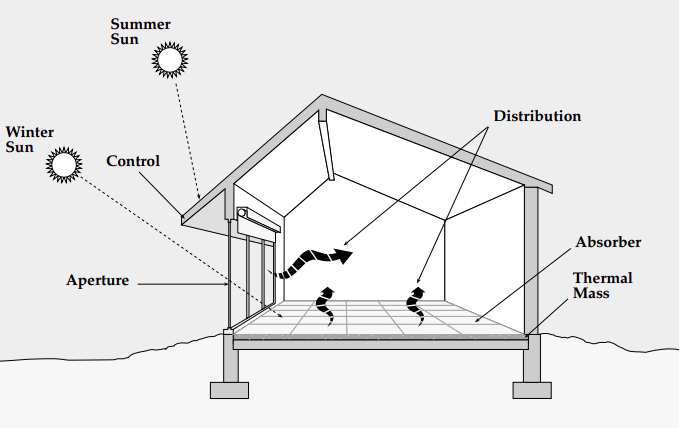

For us to model this house while keeping the project within a reasonable scope, we have made a couple assumptions:

- For the structure of the house, we are assuming the only three materials used in the construction are concrete, polyurethane foam, and glass. In our model house, the walls are entirely made of foam, the floor is made entirely of concrete, with a layer of insulation underneath, and the aperture is entirely made of insulating glass.

- For the environment of the house, we are using an incredibly simple model for the temperature of the environment. The temperature of the ground is a single sinusoidal wave with a period of 1 year, and the temperature of the air outside is the temperature of the ground, with another 24 hour period sinusoid layered on top. This obviously drastically simplifies actual air and ground temperature changes.

- For our insolation model, we are making yet another major assumption: we are assuming that throughout the whole year the house is always pointed directly towards the sunrise, with the aperture being perpendicular to the path traveled by the sun. In the real world, the azimuth of the sun actually changes throughout the year, and so to build a house that constantly faces the sunrise one would have to mount the house on a giant turntable and rotate the house throughout the year.

While these assumptions are all simplifications and abstractions, they do not fundamentally change the mathematical model of the house - it is only a matter of tweaking parameters, of numerical inaccuracy, Thus, while we will not be able to directly use the building design parameters generated by the model and the parameter sweeper, the conclusions we can draw from this project will still be valuable when considering how a passive solar house should be designed.

 From this set of abstractions, we can then build the model of the house represented here with our schematic drawing.

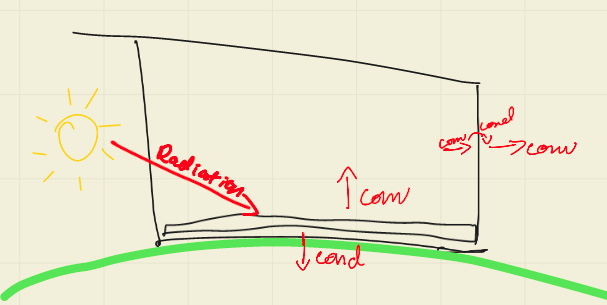

From this schematic, we can then generate a stock and flow diagram:

#### 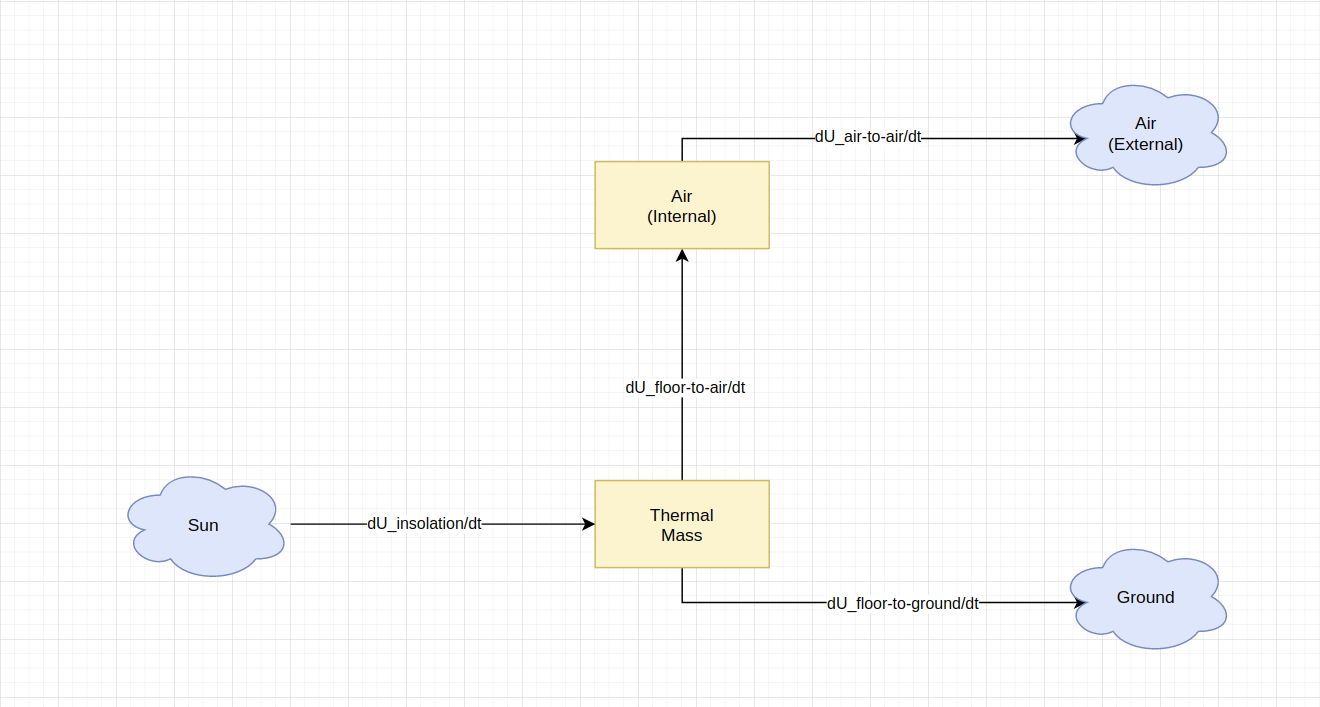

### Consolidated stock and flows:

From the stock and flow diagram we can then generate these equations for the total flows in and out of each stock:


$$\frac{dU_{air}}{dt} = \frac{dU_{floor-to-air}}{dt} - \frac{dU_{air-to-air}}{dt} \\

\frac{dU_{floor}}{dt} = \frac{dU_{insolation}}{dt} - \frac{dU_{floor-to-ground}}{dt} -  \frac{dU_{floor-to-air}}{dt} \\$$


### Equations for individual flows:

#### Energy flow from conduction/convection

General equation for heat flow when given resistances:


$$\frac{dU_{flow}}{dt} = \frac{-1}{R_{total}}\Delta T$$


For the individual heat flows, we then have:


$$\frac{dU_{floor-to-ground}}{dt} = \frac{-1}{R_{floor-to-ground}}(T_{ground} - T_{floor}) \\

\frac{dU_{floor-to-air}}{dt} = \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor})\\

\frac{dU_{air-to-air}}{dt} = \frac{-1}{R_{air-to-air}}(T_{air-outside} - T_{air-inside})$$


#### Energy from radiation (insolation)

Equation for energy from insolation:


$$\frac{dU_{insolation}}{dt} = eIA_{insolation}$$


Now to implement these equations, we just need to derive the resistances, and find the temperatures in relation to energy

### Resistances:


$$R_{air-air} = \frac{1}{2 \frac{1}{h_{air}A_{w} + \frac{d_{w}}{A_{w}k_{w}} }} + \frac{1}{2 \frac{1}{h_{air}A_{a} + \frac{d_{a}}{A_{a}k_{a}} }}$$



$$R_{floor-air} = \frac{1}{h_{air} A_{f}}$$



$$R_{floor-ground} = \frac{d}{A_fk_f$$


### Temperatures:

Formula for converting energy into temperature: $U = mcT$. Thus,

$T_{ground}$ = Given

$T_{air-outside}$= Given


$$T_{floor} = \frac{U_{floor}}{m_{floor}\ c_{floor}}$$



$$T_{air-inside} = \frac{U_{air-inside}}{m_{air-inside}\ c_{air}}$$


### Putting it all together


$$\frac{dU_{air}}{dt} = \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor}) - \frac{-1}{R_{air-to-air}}(T_{air-outside} - T_{air-inside}) \\

\frac{dU_{floor}}{dt} = eIA_{insolation} - \frac{-1}{R_{floor-to-ground}}(T_{ground} - T_{floor}) - \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor}) \\$$



$$T_{floor} = \frac{U_{floor}}{m_{floor}\ c_{floor}}$$



$$T_{air-inside} = \frac{U_{air-inside}}{m_{air-inside}\ c_{air}}$$



$$R_{air-air} = \frac{1}{2 \frac{1}{h_{air}A_{w} + \frac{d_{w}}{A_{w}k_{w}} }} + \frac{1}{2 \frac{1}{h_{air}A_{a} + \frac{d_{a}}{A_{a}k_{a}} }}$$



$$R_{floor-air} = \frac{1}{h_{air} A_{f}}$$



$$R_{floor-ground} = \frac{d}{A_fk_f$$


### Model Verification

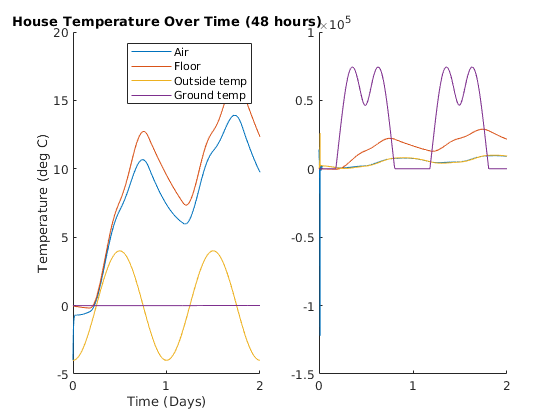

% Constant area
area_floor = 350;
height_aperture = 5;
width_aperture = 10;

% Parameters to sweep
thickness_floor = 0.2;
thickness_insulation = 0.2;

end_day = 2;
timespan = [1, end_day * (24 * 60 * 60)]; % Convert date time ranges to seconds
max_timestep = 1000;

[T, Y, debug] = house_simulate(timespan, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

% Seconds to days
T = T / (24 * 60 * 60);
debug(:, 1) = debug(:, 1) / (24 * 60 * 60);

% K to C
Y(:, 1:2) = Y(:, 1:2) - 273.15;
debug(:, 6:7) = debug(:, 6:7) - 273.15;

figure(1); clf;

subplot(1, 2, 1);
hold on;
plot(T, Y(:, 1));
plot(T, Y(:, 2));
plot(debug(:, 1), debug(:,6))
plot(debug(:, 1), debug(:,7))
legend("Air", "Floor", "Outside temp", "Ground temp");
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("House Temperature Over Time (48 hours)");

subplot(1, 2, 2)
hold on;
plot(debug(:, 1), debug(:, 2))
plot(debug(:, 1), debug(:, 3))
plot(debug(:, 1), debug(:, 4))
plot(debug(:, 1), debug(:, 5))

<Plot model debug rates? - Note that insolation values seem a bit funky with the camel humps>

<Figure with subplots of simulation for a day, a mont, and a year>

Ok now we change parameters

<Figure comparing increased wall thickness to previous, with subplot comparing rolling range>

<Figure comparing increased floor thickness to previous with subplot comapring rolling range>

Model verification complete?

## Results

## Interpretation